clc
close all
clear variables

% calculated in previous problem
Rm = 3;
Req = .25;
% measurements in order Vdc[i]=VRm[i]=fenq[i]
Vdc = [5.2;
    4.79;
    4.33;
    3.75;
    3.29;
    2.81;
    2.25;
    1.75;
    1.21;
    .71;
    .52];
Vout = [.055;
    .05;
    .045;
    .042;
    .039;
    .037;
    .032;
    .03;
    .027;
    .023;
    .021];
fenq = [2010;
    1982;
    1867;
    1627;
    1407;
    1187;
    949;
    725;
    457;
    229;
    147];
% calculations
Idc = Vout/Req;
k = sqrt((Vdc - Idc.*Rm)./fenq);
omega = (Vdc - Idc.*Rm)./k;
A = [omega ones([11 1])];
Y = k.*Idc;
B_Tint = linsolve(A,Y);

tab = array2table([Vdc Vout fenq Idc k omega],'VariableNames',{'Vdc(V)','Vout(V)','fenq(Hz)','Idc(A)','k','omega'})

tab = 11×6 table
    Vdc(V)    Vout(V)    fenq(Hz)    Idc(A)       k        omega 
    ______    _______    ________    ______    ________    ______

      5.2      0.055       2010       0.22     0.047526    95.527
     4.79       0.05       1982        0.2     0.045979    91.129
     4.33      0.045       1867       0.18     0.045055    84.119
     3.75      0.042       1627      0.168     0.044666    72.672
     3.29      0.039       1407      0.156     0.044785    63.012
     2.81      0.037       1187      0.148     0.044646    52.995
     2.25      0.032        949      0.128     0.044343    42.081
     1.75       0.03        725       0.12     0.043786    31.745
     1.21      0.027        457      0.108     0.044031    20.122
     0.71      0.023        229      0.092     0.043

B = B_Tint(1,1)

B = 6.5728e-05

T_int = B_Tint(2,1)

T_int = 0.0032

k_avg = mean(k)

k_avg = 0.0446

k_std = std(k)

k_std = 0.0013

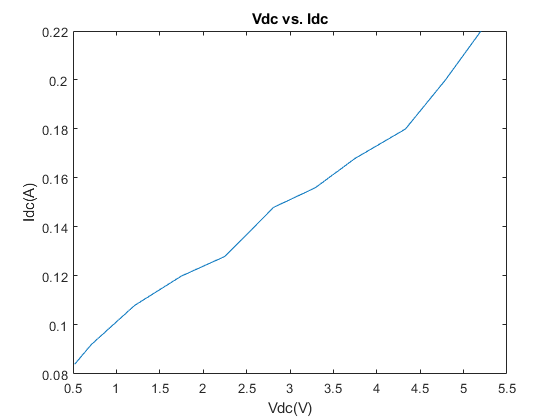


plot(Vdc, Idc)
title('Vdc vs. Idc')
xlabel('Vdc(V)');
ylabel('Idc(A)');

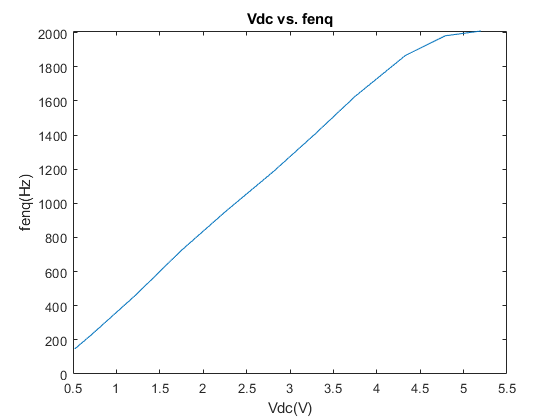

plot(Vdc,fenq)
title('Vdc vs. fenq')
xlabel('Vdc(V)');
ylabel('fenq(Hz)');     

% I = mean(Idc)
% O = mean(omega)
% V = mean(Vdc)

